# Module 2: MATLAB Data Types

## 1. Overview

Variables in MATLAB have different types, representing different forms of data (e.g. numbers, texts...). The good news is -- you don't have to declare a type and change types of varaibles during programming. In this lecture, we're going to briefly know the different types in MATLAB, and focus on the most improtant type --numeric arrays.

#### 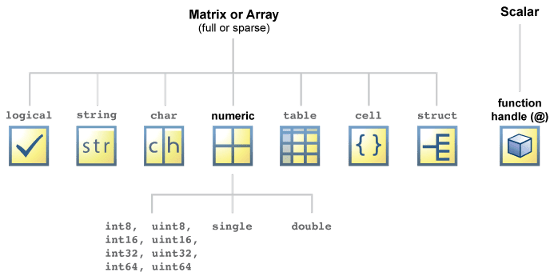

## 2. Inspecting Matlab Data Structures with "Class" Command

class(3) % note that it is not an integer by default

ans = 'double'

class([1,2,3]) % this is the numeric array

ans = 'double'

class('matlab') % note the difference with next line 

ans = 'char'

**char:** Represents text data as a sequence of characters. MATLAB stores strings as arrays of characters enclosed in single quotes (' ').

class("hello world") % You define strings without single quotes

ans = 'string'

class(true)

ans = 'logical'

**logical:** Represents binary values - either true or false. Logical data types are often used in logical operations, conditional statements, and logical indexing.

class(false)

ans = 'logical'

Here "**double**" (short for [double-precision floating-point](https://www.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html) values) is indeed the default data type for all numeric variables. Note the digits are finite in MATLAB, and therefore are indeed rational.

## **3. Matlab Numeric Arrays**

### 3.1 Different array types and size

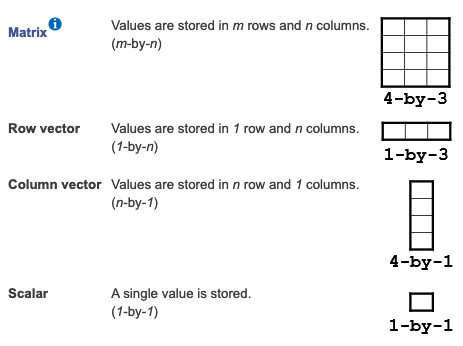

***Example 1: ***[***size***](https://www.mathworks.com/help/matlab/ref/size.html)*** function***

`size(`[`A`](https://www.mathworks.com/help/matlab/ref/size.html#bvfgzsm-1-A)`)` returns a row vector whose elements are the lengths of the corresponding dimensions of `A`. For example, if `A` is a 3-by-4 matrix, then `size(A)` returns the vector `[3 4]`.

[1,2;3,4]

ans =      1     2
     3     4


size([1,2;3,4]) % matrix, use ";" to start a new row

ans =      2     2


[1,2,3,4]

ans =      1     2     3     4


size([1,2,3,4]) % row vector 

ans =      1     4


[1;2;3;4]

ans =      1
     2
     3
     4


size([1;2;3;4]) % column vector

ans =      4     1


size(1) % scalar

ans =      1     1


### ***In-class Exercise 1***

Create the following arrays:

- column vector $\left\lbrack \begin{array}{c}
2\\
5\\
9\\
10\\
3
\end{array}\right\rbrack$;

- row vector $\left\lbrack \begin{array}{cccccc}
3 & 5 & 9 & 3 & 4 & 2
\end{array}\right\rbrack$;

- matrix $\left\lbrack \begin{array}{cc}
1 & 2\\
3 & 4\\
5 & 6
\end{array}\right\rbrack$;

- matrix $\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 2 & 0\\
0 & 0 & 3
\end{array}\right\rbrack$. (**Hint:** check out the [diag](https://www.mathworks.com/help/matlab/ref/diag.html?searchHighlight=diag&s_tid=srchtitle_support_results_1_diag) function!)

% write your code here
[2;5;9;10;3]

ans =      2
     5
     9
    10
     3


[3,5,9,3,4,2]

ans =      3     5     9     3     4     2


[1,2;3,4;5,6]

ans =      1     2
     3     4
     5     6


diag([1,2,3])

ans =      1     0     0
     0     2     0
     0     0     3


### 3.2 Different ways to create array (in additional to manually typing)

***Example 2: Evenly-spaced vector*** 

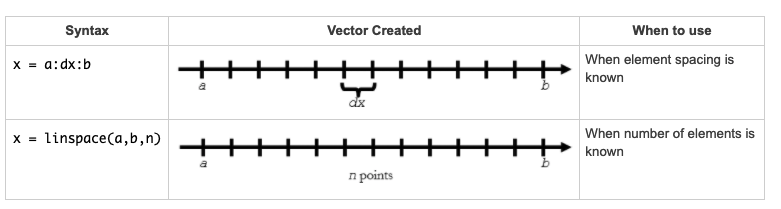

- Method 1: x=a:dx:b

v1 = 1:1e-2:2;
size(v1)

ans =      1   101


length(v1)

ans = 101

v1 % starting from 1 and ending at 2, step size = 0.01

v1 =     1.0000    1.0100    1.0200    1.0300    1.0400    1.0500    1.0600    1.0700    1.0800    1.0900    1.1000    1.1100    1.1200    1.1300    1.1400    1.1500    1.1600    1.1700    1.1800    1.1900    1.2000    1.2100    1.2200    1.2300    1.2400    1.2500    1.2600    1.2700    1.2800    1.2900    1.3000    1.3100    1.3200    1.3300    1.3400    1.3500    1.3600    1.3700    1.3800    1.3900    1.4000    1.4100    1.4200    1.4300    1.4400    1.4500    1.4600    1.4700    1.4800    1.4900


1:5 % when step size is 1, it can be omitted

ans =      1     2     3     4     5


- Method 2: using [linspace](https://www.mathworks.com/help/matlab/ref/linspace.html) function

v2 = linspace(1,2,100); % starting from 1 and ending at 2, 100 elements in total
size(v2)

ans =      1   100


v2(1:5) % the first 5 elements

ans =     1.0000    1.0101    1.0202    1.0303    1.0404


v2(end) % the last element

ans = 2

v3 = 2:-1e-2:1 % negative step size

v3 =     2.0000    1.9900    1.9800    1.9700    1.9600    1.9500    1.9400    1.9300    1.9200    1.9100    1.9000    1.8900    1.8800    1.8700    1.8600    1.8500    1.8400    1.8300    1.8200    1.8100    1.8000    1.7900    1.7800    1.7700    1.7600    1.7500    1.7400    1.7300    1.7200    1.7100    1.7000    1.6900    1.6800    1.6700    1.6600    1.6500    1.6400    1.6300    1.6200    1.6100    1.6000    1.5900    1.5800    1.5700    1.5600    1.5500    1.5400    1.5300    1.5200    1.5100


size(v3)

ans =      1   101


v4 = linspace(2,1,100)

v4 =     2.0000    1.9899    1.9798    1.9697    1.9596    1.9495    1.9394    1.9293    1.9192    1.9091    1.8990    1.8889    1.8788    1.8687    1.8586    1.8485    1.8384    1.8283    1.8182    1.8081    1.7980    1.7879    1.7778    1.7677    1.7576    1.7475    1.7374    1.7273    1.7172    1.7071    1.6970    1.6869    1.6768    1.6667    1.6566    1.6465    1.6364    1.6263    1.6162    1.6061    1.5960    1.5859    1.5758    1.5657    1.5556    1.5455    1.5354    1.5253    1.5152    1.5051


v5 = 1:2:6.1

v5 =      1     3     5


**Question 1:** What are the differences between Method 1 and 2?

Method 1 -- controls the step size. Method 2 -- controls the total number of elements.

**Question 2:** What if we want a evenly-spaced column vector?

linspace(0,5,6)'

ans =      0
     1
     2
     3
     4
     5


### 3.3 Concatenation ("merge")

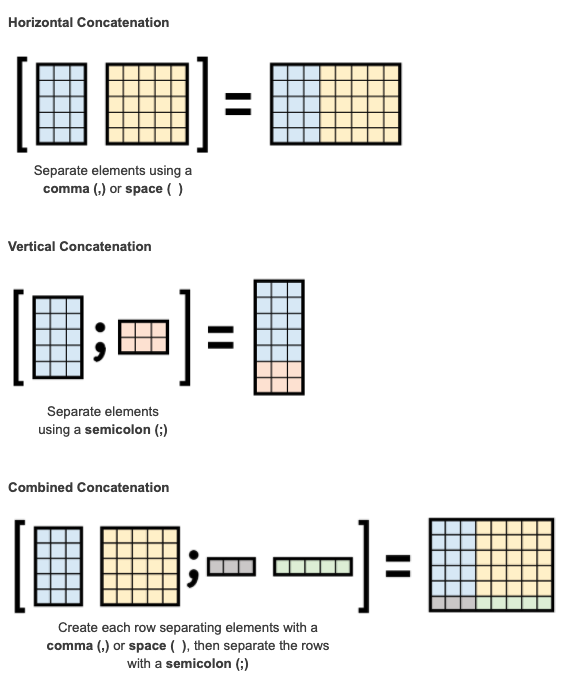

v1 = [1 2]

v1 =      1     2


v2 = [3 4]

v2 =      3     4


v3 = [v1;v2] % vertical

v3 =      1     2
     3     4


v4 = [v1 v2] % horizonal

v4 =      1     2     3     4


[v3;v2] % wrong, size does not match

ans =      1     2
     3     4
     3     4


[v3 v4] % wrong, size does not match

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

### ***In-class Exercise 2***

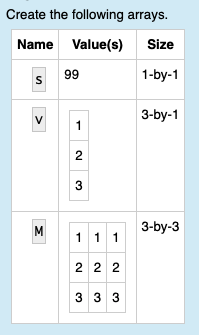

% write your code here
s = 99

s =     99


v = [1;2;3]

v =      1
     2
     3


m = [v v v]

m =      1     1     1
     2     2     2
     3     3     3


### ***In-class Exercise 3***

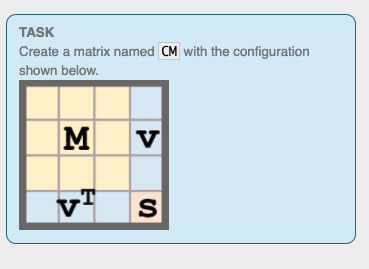

% write your code here
cm = [m v;v' s]

cm =      1     1     1     1
     2     2     2     2
     3     3     3     3
     1     2     3    99


### ***In-class Exercise 4***

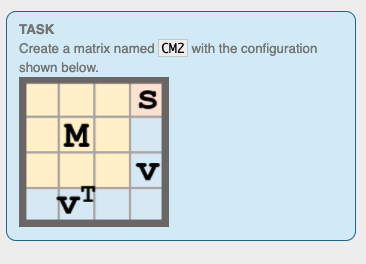

% write your code here
cm2 = [[m;v'] [s;v]]

cm2 =      1     1     1    99
     2     2     2     1
     3     3     3     2
     1     2     3     3


### 3.4 Creating numeric arrays using different functions

zeros(2,3) % all zero 2-by-3

ans =      0     0     0
     0     0     0


ones(3,1) % all one

ans =      1
     1
     1


zeros(5) % square matrix 5-by-5

ans =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


diag([1,2,3]) % create diagonal matrix

ans =      1     0     0
     0     2     0
     0     0     3


rand(6) % all random number with uniform distribution bewteen 0 and 1

ans =     0.2511    0.5497    0.5678    0.1299    0.7943    0.6541
    0.6160    0.9172    0.0759    0.5688    0.3112    0.6892
    0.4733    0.2858    0.0540    0.4694    0.5285    0.7482
    0.3517    0.7572    0.5308    0.0119    0.1656    0.4505
    0.8308    0.7537    0.7792    0.3371    0.6020    0.0838
    0.5853    0.3804    0.9340    0.1622    0.2630    0.2290


randi([10 50],1,5) % generate 5 random integers from the uniform distribution between 10 and 50.

ans =     47    16    43    32    50


### 3.5 Data selection and modification in numeric arrays

***Example 3: Numeric Indexing***

v = 2:2:20;
v

v =      2     4     6     8    10    12    14    16    18    20


% single selection: put the number into ()
v(2) % select the second element

ans = 4

v(end) % select the last element

ans = 20

v(end-1) % select the one before the last element

ans = 18

% multiple selection: put the array into ()
v(1:2:end)

ans =      2     6    10    14    18


**Logic: "1:2:end" when "end=10" --> 1,3,5,7,9 --> select v(1), v(3), v(5), v(7), v(9)**

v([2,4,5])

ans =      4     8    10


***Example 4: Modify the value***

v1 = v; % make a copy of v
v1(1:2:end) = 0; % change v(1), v(3), v(5), v(7), v(9) to 0
v1

v1 =      0     4     0     8     0    12     0    16     0    20


v2 = v;
v2([2,3,4]) = zeros(1,3);
v2

v2 =      2     0     0     0    10    12    14    16    18    20


v3 = v;
v3([2,3,4]) = 0;
v3

v3 =      2     0     0     0    10    12    14    16    18    20


% for the matrix
A = reshape(v,5,2) % change v into 5-by-2 , by default matlab is column pivot

A =      2    12
     4    14
     6    16
     8    18
    10    20


A(2,end) % the last element of the second row

ans = 14

A(2:4,2) % the second element of row 2:4

ans =     14
    16
    18


A(4,:) % the 4th row,  note this is different with A(4)

ans =      8    18


A(:,2) % the 2nd column, note this is different with A(2)

ans =     12
    14
    16
    18
    20


A([2,5],1) % submatrix: intersections of row 2, row 5, and column 1

ans =      4
    10


A([2,5],2)

ans =     14
    20


A([2,5],[1,2]) % submatrix

ans =      4    14
    10    20


A(9) % matrix is first "flattened" column-wise, then select as if it is a vector

ans = 18

### 3.6 Logical Indexing

v = 1:4 % generate a vector

v =      1     2     3     4


idx1 = [false, false, true, true] % generate a logical array

idx1 = 1×4 logical array
   0   0   1   1


v(idx1) % select the element when "idx1 = true"

ans =      3     4


idx2 = v>2 % for every element of v, check if it is larger than 2 (true or false)

idx2 = 1×4 logical array
   0   0   1   1


v(idx2) % find the element that are larger than 2

ans =      3     4


v(v>2) % equivalent and faster way

ans =      3     4


R = rand(5)

R =     0.4359    0.8176    0.5328    0.6225    0.2305
    0.4468    0.7948    0.3507    0.5870    0.8443
    0.3063    0.6443    0.9390    0.2077    0.1948
    0.5085    0.3786    0.8759    0.3012    0.2259
    0.5108    0.8116    0.5502    0.4709    0.1707


R(R>.5)

ans =     0.5085
    0.5108
    0.8176
    0.7948
    0.6443
    0.8116
    0.5328
    0.9390
    0.8759
    0.5502


% what if we want to know the location?
idx3 = R>.5 

idx3 = 5×5 logical array
   0   1   1   1   0
   0   1   0   1   1
   0   1   1   0   0
   1   0   1   0   0
   1   1   1   0   0


## 4. Other useful links

**Array Indexing help page in MATLAB: **[https://www.mathworks.com/help/matlab/math/array-indexing.html](https://www.mathworks.com/help/matlab/math/array-indexing.html)

**Christopher Davis**’s videos about MATLAB: [https://www.youtube.com/playlist?list=PLHfGN68wSbbLOFWE0Z_uFLdXjax-evW-h](https://www.youtube.com/playlist?list=PLHfGN68wSbbLOFWE0Z_uFLdXjax-evW-h)

**Yasmeen Baki**’s videos about MATLAB: [https://www.youtube.com/playlist?list=PL6ue_xaI6w4NFUSQqGkzwnW1jJgfP5tNG](https://www.youtube.com/playlist?list=PL6ue_xaI6w4NFUSQqGkzwnW1jJgfP5tNG) 